# ModSim Project 1 - SIR Model

*Authors:* Lili Baker, Olivia Chang, Tyler Ewald

*Our Learning Objectives:* As a result of writing this notebook, we (the authors) hope to:

- **Work on real world models: **Gain experience modeling the real world and learn to test model on “real world” data. Better understand how to structure and choose a type of model for real world scenario.

- **Interpretation and iteration: **Learn how to analyze a model and improve upon it; get better at interpreting and explaining model data

- **Coding Best Practices:** Improve code commenting to help debug and ensure others can understand code 

### Modeling Question

What public health interventions are most likely to be effective in reducing total number of infections in an SIR model of the flu? We will consider interventions aimed at changing the infection rate, the recovery rate, rate, or the rate at which people become able to be re-infected.

## Model Parameters

The following are the parameters of the model:

- **beta:** infectivity of disease

- **gamma **is determined by the length of recovery period

- **alpha **is determined by the community rate of vaccination

- **omega **is determined by how long it takes to lose immunity

## How to Calculate and Interpret Model Results

**What does total mean? **Total infections is the number of distinct individual flu cases. if someone is infected twice (in the first flu season, then the second) then their situation will be counted as two cases.

## Global Variables

These are variables that don't change from simulation to simulation! We've defined them as global here because we want to be able to access them across multiple functions.

Note: for every function that needs these variables, the first line of code `global num_steps i_0 s_0 r_0;` must be added in the top.

global num_steps i_0 s_0 r_0;
num_steps = 104;
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

## Model Baseline

The following model is our baseline, against which each additonal simulation will be compared. This baseline:

- **Excludes vaccinations:** no one is vaccinated in this scenario

- **Lost immunity: **Assumes everyone loses immunity after 52 weeks of recovery

- **Time span: **Runs over the course of 104 weeks, or 2 years (steps).

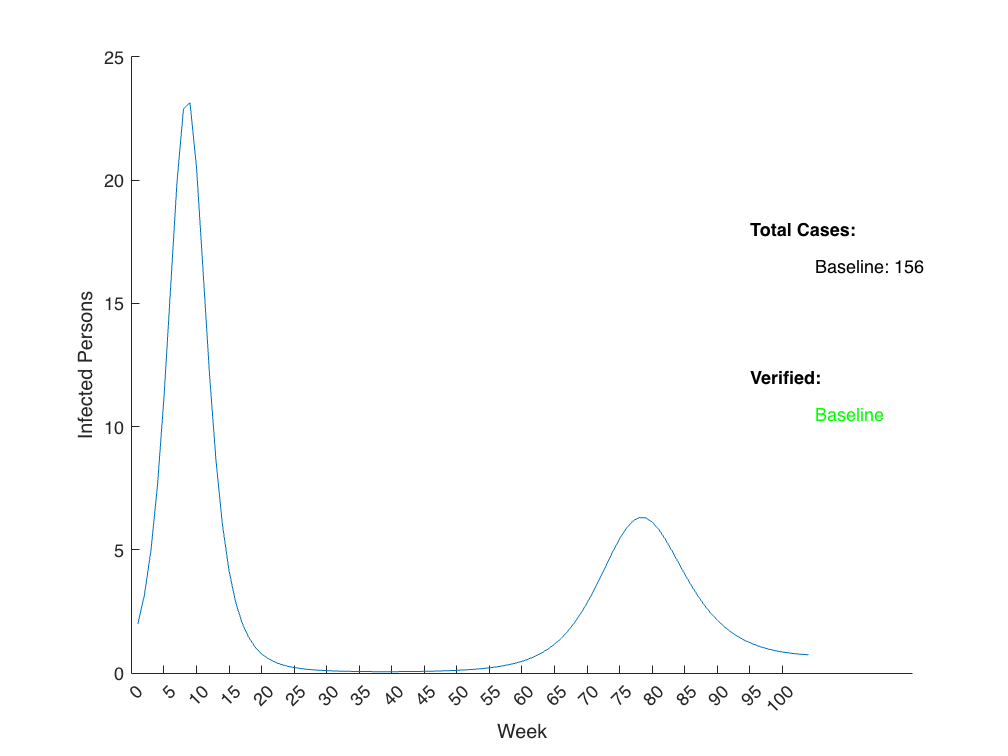

ans = 155.9205

plot_baseline()

**Interpretation:** As we can see from the chart, this model shows two times in which the number of infected persons peaks—thus flu seasons—over the course of two years. The second flu season has a smaller peak than the first, showing that the second flu season is less severe than the first.

TODO: add more

## Part 1: Interventions Which Affect The Flow From Susceptible to Recovered

Vaccinations!

How expensive is it to develop vaccinations?

Talk about likely vaccination rates, and vaccination 

How expensive is it to run these interventions?

## 5% Vaccination Model

- Assumes 5% of the total population is being vaccinated each week.

- Assumes immunity is lost after a period of time.

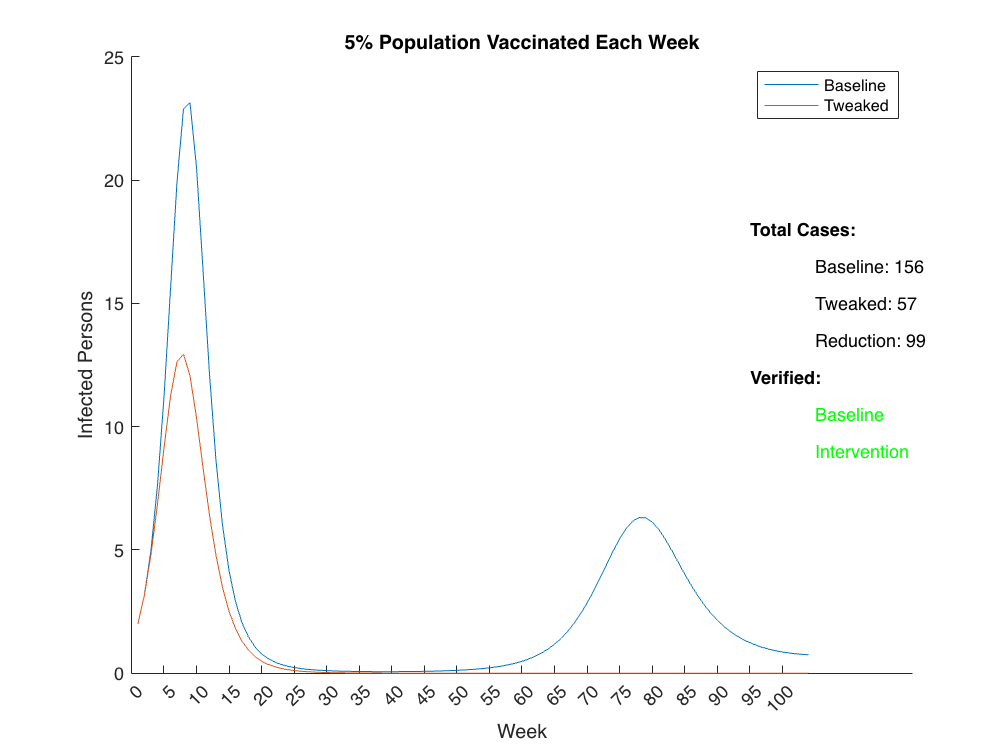

simulation_name = "5% Population Vaccinated Each Week";
I_total_baseline = plot_baseline();

% Define flow parameters
beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.05;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

**Interpretation:** If a public health campaign were executed in which 5% of the community was vaccinated per week, the number of cases would drop significantly, and prevent the emergence of a second flu season entirely.

TODO: can we check that this makes sense?

## 10% Vaccination Model

- Assumes 10% of the total population is being vaccinated each week.

- Assumes immunity is lost after a period of time.

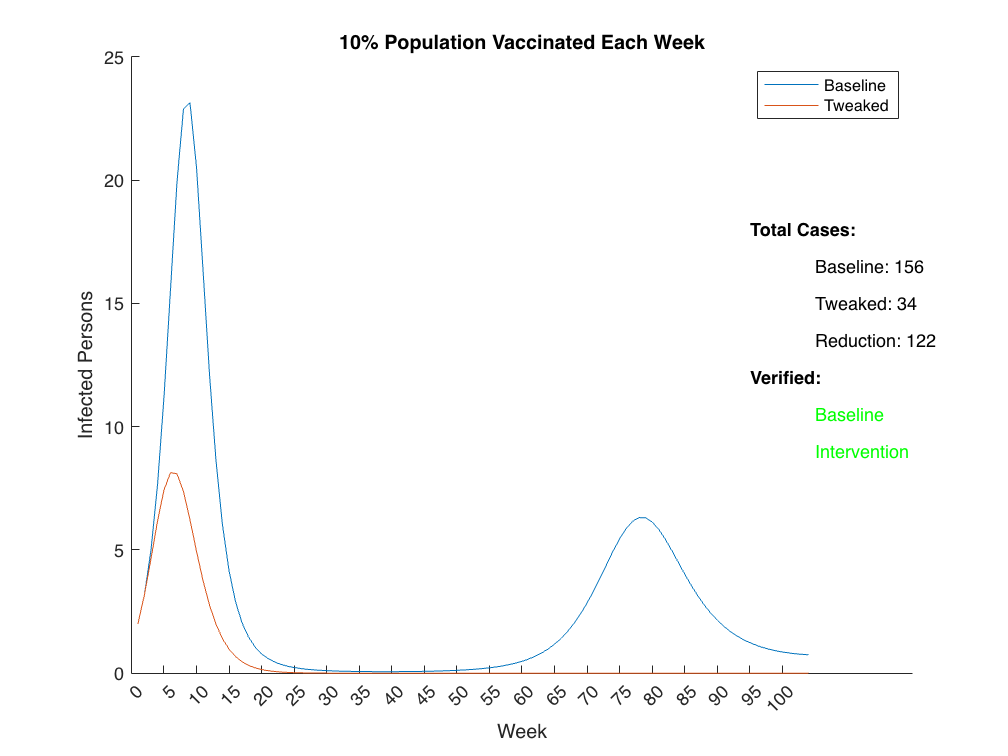

simulation_name = "10% Population Vaccinated Each Week";
I_total_baseline = plot_baseline();

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.1;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## Part 2: Interventions Which Affect The Flow From Infected to Recovered

Treatments!

how expensive is it to develop, adminster, etc

how did we find our data

## Reduce Infectious Time By 1 Day

- No vaccinations

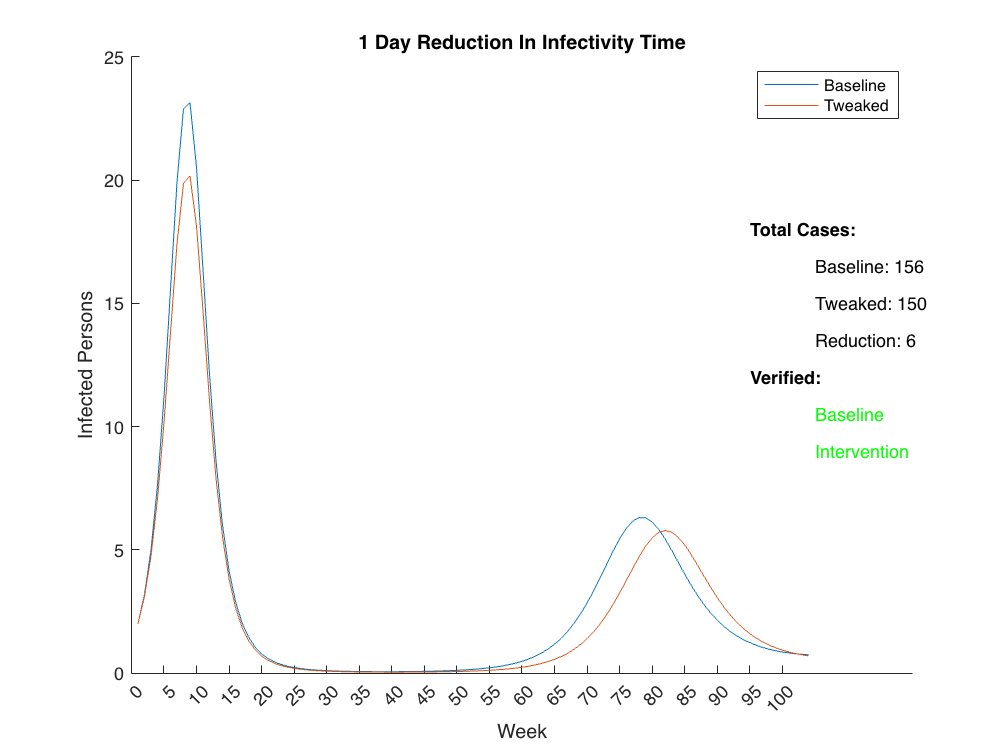

simulation_name = "1 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 1;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## Reduce Infectious Time By 2 Days

- No vaccinations

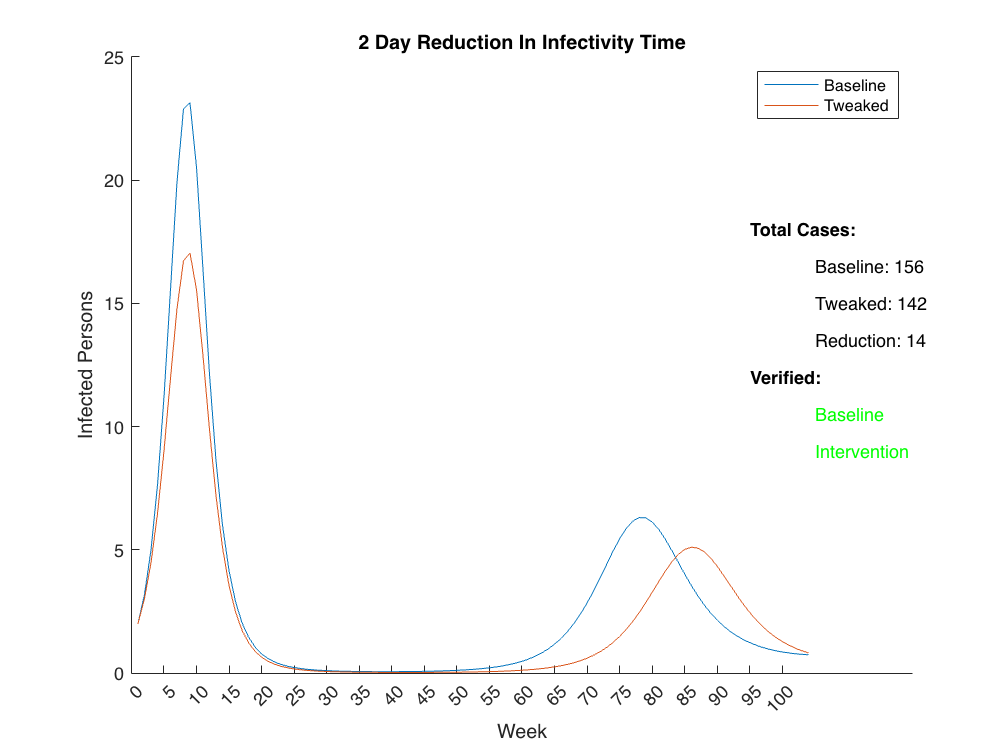

simulation_name = "2 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 2;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## Reduce Infectious Time By 3 Days

- No vaccinations

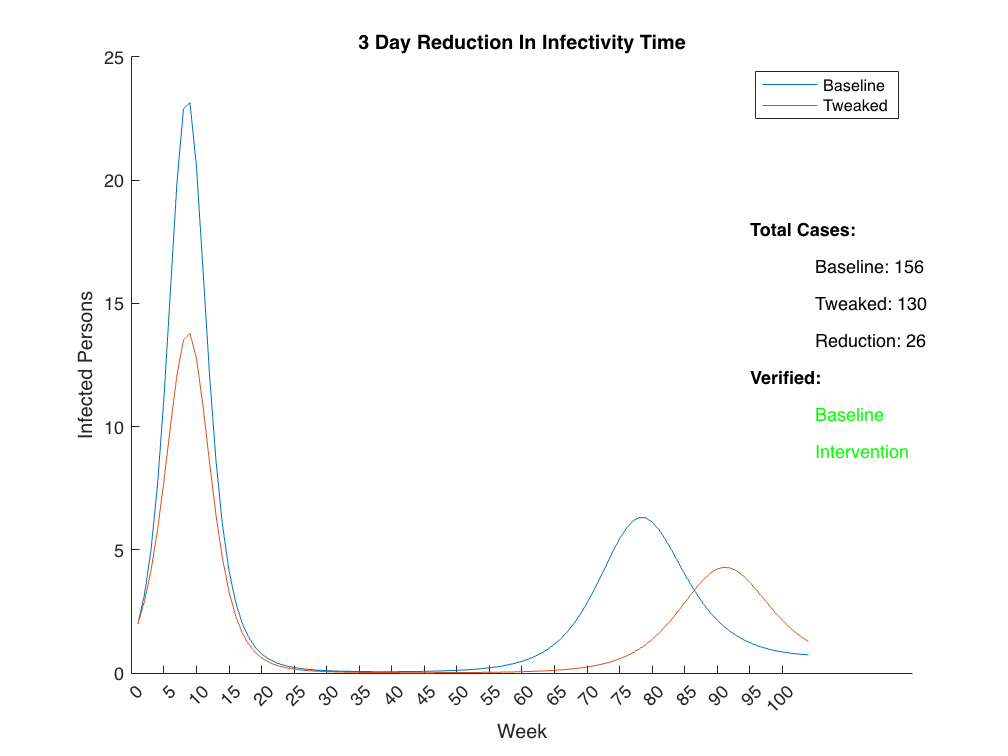

simulation_name = "3 Day Reduction In Infectivity Time";
I_total_baseline = plot_baseline();

reduction_infectious_time = 3;
infected_time = (2*7 - reduction_infectious_time) / 7;
beta = 1 / 90;
gamma = 1 / infected_time;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## Part 3: Interventions Which Affect The Flow From Susceptible to Infected

Masks, social distancing, quarantine

how we found the data

## Home Confinement with 50% Compliance Rate

- Assumes 50% of the population is quaranting at home.

- No vaccinations.

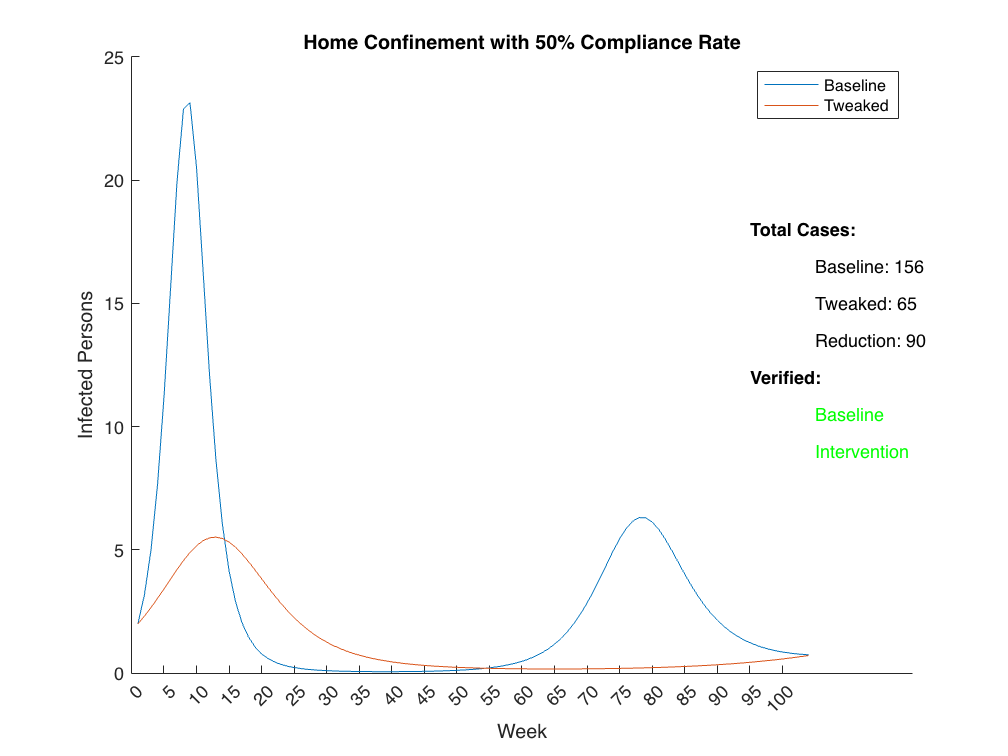

simulation_name = "Home Confinement with 50% Compliance Rate";
I_total_baseline = plot_baseline();

decreaseInAttack = 0.604;
beta = (1 / 90) * decreaseInAttack;
gamma = 1 / 2;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## School Closures for Three Weeks

- Assumes schools are closed for three weeks.

- No vaccinations.

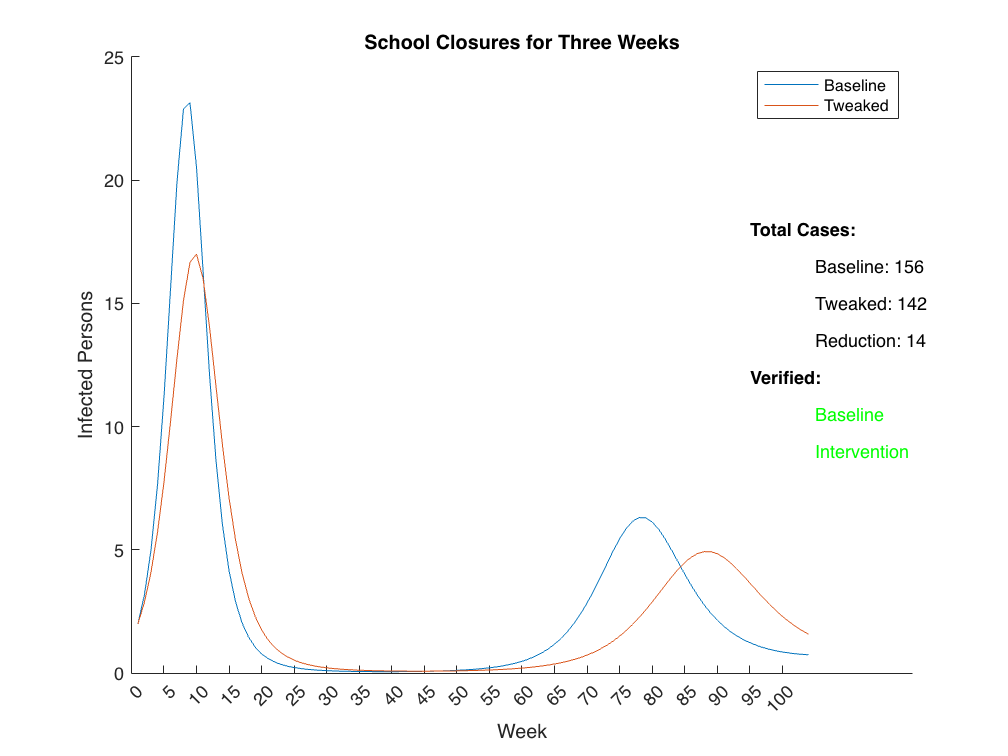

simulation_name = "School Closures for Three Weeks";
I_total_baseline = plot_baseline();

decreaseInAttack = 0.861;;
beta = (1 / 90) * decreaseInAttack;
gamma = 1 / 2;
alpha = 0;
omega = 1 / 52;

plot_intervention(beta, gamma, alpha, omega, I_total_baseline, simulation_name)

## Verification

### Constant Number of People

explain verify.m (we should rename this to verifyPop.m)

### Total Number of Infected and Vaccinated Never Exceeds Number of Susceptible

explain how we verified flows

Constrained values

### Number of People Recovering Never Exceeds Number of Infected People

Constrained values

## Validation

## Sources